# AMECH HW5

*Steven Henderson*

**Problem 1**

A periodic force F (t) has period T and is defined in the interval $-\frac{T}{2}$ ≤ t ≤ $\frac{T}{2}$ as


$$F\left(t\right)=F_0 \frac{2t}{T}$$


This is a periodic right-angle sawtooth, see the figure below. The force is driving a one-dimesional damped harmonic oscillator system


$$F\left(t\right)=\overset{\ldotp \ldotp }{\textrm{mx}} +2m\gamma \overset{\ldotp }{x} +\textrm{kx}$$


**(A) **Expand the force in Fourier series and give an expression for the nth term in the

expansion.


$$\begin{array}{l}
F\left(t\right)=\frac{A_0 }{2}+\sum_{n=1}^{\infty } \left\lbrack A_n \cos \left(\omega_n t\right)+B_n \sin \left(\omega_n t\right)\right\rbrack \\
A_n =\frac{2}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} F\left(t\right)\cos \left(\omega_n t\right)\textrm{dt},F\left(t\right)\;\textrm{is}\;\textrm{an}\;\textrm{odd}\;\textrm{function}\;\textrm{so}\;\textrm{odd}\;\textrm{times}\;\textrm{even}\;\textrm{is}\;\textrm{odd}\;\textrm{making},\\
A_n =0
\end{array}$$



$$\begin{array}{l}
B_n =\frac{2}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} F\left(t\right)\sin \left(\omega_n t\right)\textrm{dt}=\frac{8}{T^2 }F_0 \int_0^{\frac{T}{2}} \textrm{tsin}\left(\omega_n t\right)\textrm{dt},\textrm{integration}\;\textrm{by}\;\textrm{parts}\\
u=t,\textrm{dv}=\sin \left(\omega_n t\right),\textrm{du}=\textrm{dt},v=-\frac{\cos \left(\omega_n t\right)}{\omega_n }\\
B_n =\frac{8}{T^2 }F_0 \left({}{\left\lbrack -\frac{\textrm{tcos}\left(\omega_n t\right)}{\omega_n }\right\rbrack }^{\frac{T}{2}}_0+\frac{1}{\omega_n }\int_0^{\frac{T}{2}} \cos \left(\omega_n t\right)\textrm{dt}\right)\\
B_n =8\frac{F_0 }{T^2 }\left(\left\lbrack -\frac{\textrm{Tcos}\left(\omega_n \frac{T}{2}\right)}{2\omega_n }\right\rbrack +\frac{1}{\omega_n }{}{\left\lbrack \frac{\sin \left(\omega_n t\right)}{\omega_n }\right\rbrack }^{\frac{T}{2}}_0\right)\\
\omega_n =2\pi \frac{n}{T}
\end{array}$$



$$B_n =\frac{8F_0 }{T^2 }\left(-\frac{T^2 \cos \left(\pi n\right)}{4\pi n}+\frac{T^2 \sin \left(\pi n\right)}{4\pi^2 n^2 }\right)={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}$$



$$F_n \left(t\right)={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}\sin \left(\omega_n t\right)$$


**(B)** For mass m = 1 kg, T = 1 sec, and F`0` = 500 N, use MATLAB to plot the analytic

function of the force and overlay the force as calculated through the Fourier expansion

with n ≤ 5. Use the help provided below to plot the right angle sawtooth.

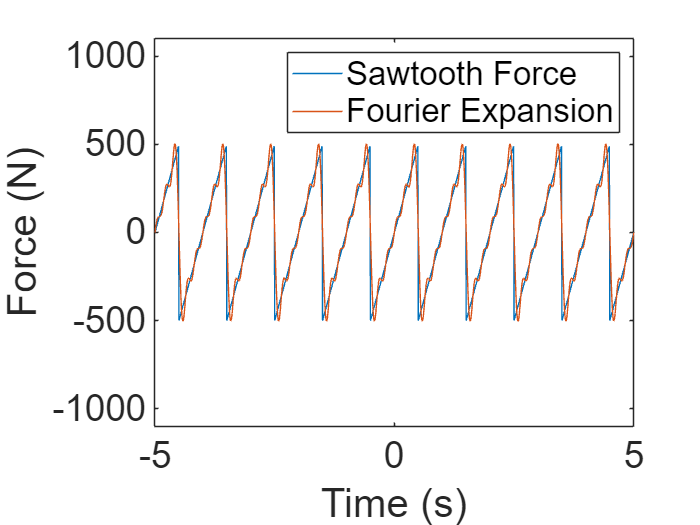

% Initial Variables
m = 1 ; % mass (kg)
T = 1 ; % period (s)
F_0 = 500 ; % initial force (N)
% Right Angle Sawtooth
time = -5:0.01:5 ; % s time array
A = 1000 ; % N/kg, mass normalized force constant peak-to-peak
period = 1 ; % sec, period of drive
Force = mod(A.*(time+period/2)./period,A) - A/2 ; % normalized force
% Loop 5 times over adding all terms to F
F = 0 ;
for n = 1:5
    F = F + (-1)^(n+1)*2*F_0/(pi*n).*sin(2*pi*n/T.*time) ;
end
% Plot results
plot(time, Force)
hold on
plot(time, F)
xlabel('Time (s)')
ylabel('Force (N)')
set(gca, 'fontsize', 22)
legend('Sawtooth Force', 'Fourier Expansion')
ylim([-1100, 1100])
hold off

**(C) **In steady state, the displacement of the mass in response to this driving force (with

n ≤ 5) is


$$x\left(t\right)=\sum_{n=1}^5 x_n \left(t\right)$$


In a single figure, plot each of the xi(t) assuming that the damping constant is γ = 0.75,

and the natural frequency of the system is 60 rad/s.


$$\begin{array}{l}
F_n \left(t\right)={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}\sin \left(\omega_n t\right)=m{\overset{\ldotp \ldotp }{x} }_n +2m\gamma {\overset{\ldotp }{x} }_n +{\textrm{kx}}_n \\
f\left(t\right)=\frac{\left({\left(-1\right)}^{n+1} 2\frac{F_0 }{\pi n}\sin \left(\omega_n t\right)\right)}{m}\\
f\left(t\right)={\overset{\ldotp \ldotp }{x} }_n +2\gamma {\overset{\ldotp }{x} }_n +{\omega_0^2 x}_n ,\textrm{where}\;\omega_0 =\sqrt{\frac{k}{m}}\\
\textrm{finding}\;\textrm{general}\;\textrm{solution}\;\left(\textrm{use}\;\textrm{no}\;\textrm{driven}\right)\\
m{\overset{\ldotp \ldotp }{x} }_n +2m\gamma {\overset{\ldotp }{x} }_n +{\textrm{kx}}_n =0\\
{\overset{\ldotp \ldotp }{x} }_n +2\gamma {\overset{\ldotp }{x} }_n +{\omega_0^2 x}_n =0,\\
D=\frac{d}{\textrm{dt}}\\
\left(D^2 +2\gamma D+\omega_0^2 \right)x=0\\
\left(D-r_1 \right)\left(D-r_2 \right)x=0
\end{array}$$



$$\begin{array}{l}
x_n \left(t\right)=C_1 e^{r_1 t} +C_2 e^{r_2 t} \\
\textrm{Quadratic}:\\
r_{1,2} =\frac{-2\gamma \pm \sqrt{4\gamma^2 -4\omega_0^2 }}{2}=-\gamma \pm \sqrt{\gamma^2 -\omega_0^2 }\\
\gamma <\omega_0 \;\textrm{underdamped}\\
\sqrt{\gamma^2 -\omega_0^2 }=i\sqrt{\omega_0^2 -\gamma^2 }=i\omega_1 \\
x_n \left(t\right)=e^{-\gamma t} \left(C_1 e^{i\omega_1 t} +C_2 e^{-i\omega_1 t} \right)={\textrm{Ae}}^{-\gamma t} \cos \left(\omega_1 t+\phi \right)
\end{array}$$


Finding Particular


$$\begin{array}{l}
m{\overset{\ldotp \ldotp }{x} }_n +2m\gamma {\overset{\ldotp }{x} }_n +{\textrm{kx}}_n ={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}\sin \left(\omega_n t\right)\\
{\overset{\ldotp \ldotp }{x} }_n +2\gamma {\overset{\ldotp }{x} }_n +{\omega_0^2 x}_n =f_0 \left(t\right)\\
f_0 \left(t\right)=f_0 e^{i\omega t} \\
x\left(t\right)=\textrm{Re}\left(z\right),\textrm{where}\;z\;\textrm{is}\;\textrm{in}\;\textrm{place}\;\textrm{of}\;x\;\textrm{as}\;x\;\textrm{is}\;\textrm{complex}\\
\overset{\ldotp \ldotp }{z} +2\gamma \overset{\ldotp }{z} +\omega_0^2 z=f_0 e^{i\omega t} \\
\textrm{guess}\;z={\textrm{Ce}}^{i\omega t} \\
\overset{\ldotp }{z} =\textrm{iC}\omega e^{i\omega t} \\
\overset{\ldotp \ldotp }{z} =-C\omega^2 e^{i\omega t} 
\end{array}$$



$$\begin{array}{l}
-C\omega^2 e^{i\omega t} +2\gamma \textrm{iC}\omega e^{i\omega t} +\omega_0^2 {\textrm{Ce}}^{i\omega t} =f_0 e^{i\omega t} \\
-C\omega^2 +\textrm{i2C}\omega \gamma +\omega_0^2 C=f_0 \\
C=\frac{f_0 }{-\omega^2 +\textrm{i2}\omega \gamma +\omega_0^2 }=\frac{f_0 \left(\omega_0^2 -\omega^2 \right)-{\textrm{if}}_0 \omega^2 \gamma }{{\left(\omega_0^2 -\omega^2 \right)}^2 +\omega^2 4\gamma^2 }
\end{array}$$



$$\begin{array}{l}
C=\left(\frac{f_0 }{\left(\omega_0^2 -\omega^2 \right)+\omega^2 4\gamma^2 }\right)\left(\left(\omega_0^2 -\omega^2 \right)-i\omega 2\gamma \right)\\
\theta =\tan^{-1} \left(\frac{2\omega \gamma }{\omega^2 -\omega_0^2 }\right)\\
r=\sqrt{{\left(\omega_0^2 -\omega^2 \right)}^2 +{4\omega }^2 \gamma^2 }
\end{array}$$



$$x_p \left(t\right)=\textrm{Re}\left\lbrace \frac{f_0 }{\sqrt{\omega_0^2 -\omega^2 +4\omega^2 \gamma^2 }}e^{i\omega t+\theta } \right\rbrace =\frac{f_0 }{\sqrt{{\left(\omega_0^2 -\omega^2 \right)}^2 +4\omega^2 \gamma^2 }}\cos \left(\omega t+\theta \right)$$



$$\begin{array}{l}
m{\overset{\ldotp \ldotp }{x} }_n +2m\gamma {\overset{\ldotp }{x} }_n +{\textrm{kx}}_n ={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi n}\sin \left(\omega_n t\right)\\
{\overset{\ldotp \ldotp }{x} }_n +2\gamma {\overset{\ldotp }{x} }_n +{\omega_0^2 x}_n ={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi \textrm{nm}}\sin \left(\omega_n t\right)\\
{\overset{\ldotp \ldotp }{x} }_n ={\left(-1\right)}^{n+1} \frac{2F_0 }{\pi \textrm{nm}}\sin \left(\omega_n t\right)-{\omega_0^2 x}_n -2\gamma {\overset{\ldotp }{x} }_n 
\end{array}$$


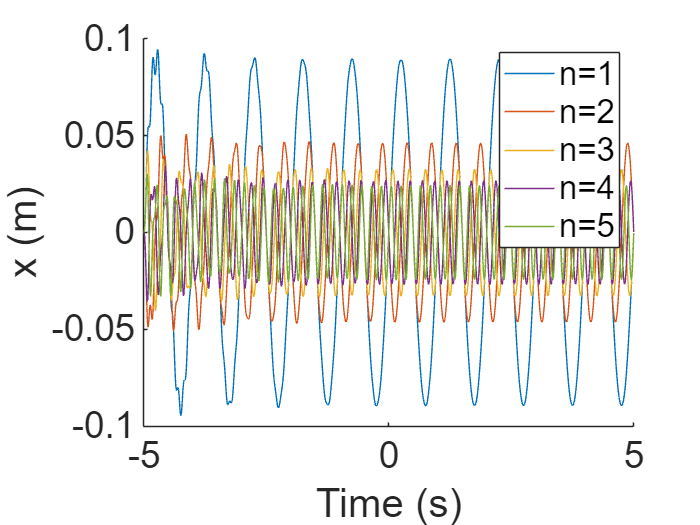

function xdot = myode(t, x, n)
    % Initial Variables
    m = 1 ;
    T = 1 ;
    F_0 = 500 ;
    gamma = 0.75 ;
    omega_0 = 60 ;
    omega = 2*pi*n/T ;
    %
    xdot(1) = x(2) ;
    xdot(2) = ((-1)^(n+1)) * ((2*F_0)/(pi*n*m)) * sin(omega*t) - (omega_0^2)*x(1) - 2*gamma*x(2) ;
    xdot = xdot' ;
end
ix = [0, 0] ;
clf
hold on
x_n = zeros(1001, 5) ;
for n = 1:5
    [t, x] = ode45(@(t, x)myode(t, x, n), time, ix) ;
    plot(t, x(:, 1))
    x_n(:, n) = x(:, 1) ;
end
xlabel('Time (s)')
ylabel('x (m)')
set(gca, 'fontsize', 22)
legend('n=1', 'n=2', 'n=3', 'n=4', 'n=5')

(D) In an additional figure, plot the displacement of the mass x(t). Which of the harmonics contributes most for the displacement? Is any of the contributions much larger than he others, or are they all comparable? (Much larger would at least `×`10 larger than any other) What is the maximum displacement x? Does the displacement resemble the shape of the periodic force?

x_t = x_n(:,1)+x_n(:,2)+x_n(:,3)+x_n(:,4)

x_t =          0
    0.0000
    0.0000
    0.0001
    0.0006
    0.0016
    0.0035
    0.0066
    0.0110
    0.0166


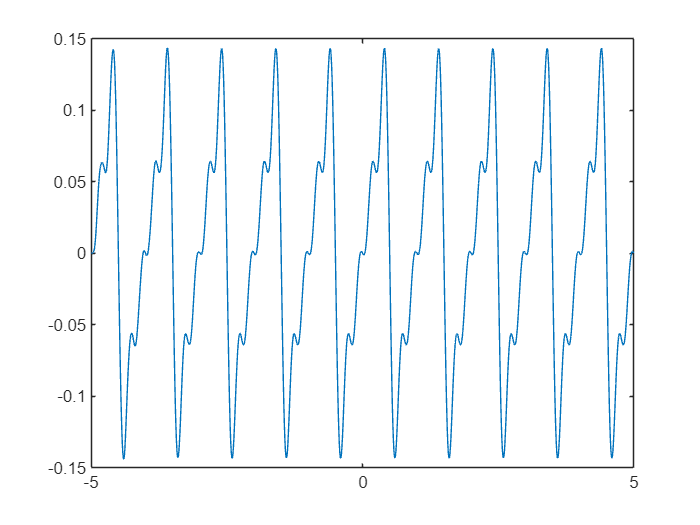

clf
plot(t, x_t)

**Problem 2**

Understanding the behavior of the CO`2` molecule is critical for understanding climate change. The molecule is co-linear with the oxygen atoms bracketing a central carbon atom, all along a straight line (see, for example, wikipedia). The connections between the atoms can be considered springs, making a system of three masses connected with two equal springs. We will only consider 1-dimensional motions along the line connecting the atoms. (The moleculedoes ’bend’ as well, a mode that is also important for climate change. ) Set useful coordinates and solve for the general motion of the molecule.

**(A)** Find the Lagrangian.


$$\begin{array}{l}
V=\frac{1}{2}\left\lbrack k{\left(x_1 -x_2 \right)}^2 +k{\left(x_2 -x_3 \right)}^2 \right\rbrack ,\textrm{where}\;x_{n\;} \textrm{is}\;\textrm{the}\;\textrm{displacement}\;\textrm{of}\;\textrm{the}\;\textrm{mass}\\
K=\frac{1}{2}\left(m_1 v_1^2 +m_2 v_2^2 +m_3^2 \right)\\
L=\frac{1}{2}\left(m_1 v_1^2 +m_2 v_2^2 +m_3^2 \right)-\frac{1}{2}\left\lbrack k{\left(x_1 -x_2 \right)}^2 +k{\left(x_2 -x_3 \right)}^2 \right\rbrack 
\end{array}$$



$$\begin{array}{l}
\frac{\partial L}{\partial x_1 }=-k\left(x_1 -x_2 \right)\\
\frac{\partial L}{\partial x_2 }=-k\left(x_2 -x_1 \right)-k\left(x_2 -x_3 \right)\\
\frac{\partial L}{\partial x_3 }={-k} \left(x_3 -x_2 \right)\\
\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_1 }\right)=m_1 \overset{\ldotp \ldotp }{x_1 } \\
\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_2 }\right)=m_2 \overset{\ldotp \ldotp }{x_2 } \\
\frac{d}{\textrm{dt}}\left(\frac{\partial L}{\partial {\overset{\ldotp }{x} }_3 }\right)=m_3 \overset{\ldotp \ldotp }{x_3 } 
\end{array}$$


**(B)** Formulate the equations of motion in matrix form and use MATLAB to find the normal frequencies and normal modes assuming the known masses of the atoms and k = 840 N/m. To get a more tangible idea of the normal frequencies, express them in wavelength inmicrometer (≡ μm) and wavenumber in cm`−``1`. Wavenumber ≡ `1 `wavelength .


$$\begin{array}{l}
m_1 \overset{\ldotp \ldotp }{x_1 } =-k\left(x_1 -x_2 \right)=k x_2 -k x_1 \\
m_2 \overset{\ldotp \ldotp }{x_2 } ={-k} \left(x_2 -x_1 \right)-k \left(x_2 -x_3 \right)=k x_1 -k x_2 +k x_3 -kx_2 \\
m_3 \overset{\ldotp \ldotp }{x_3 } ={-k} \left(x_3 -x_2 \right)=k x_2 -k x_3 
\end{array}$$



$$\begin{array}{l}
\vec{M} =\left\lbrack \begin{array}{ccc}
m_1  & 0 & 0\\
0 & m_2  & 0\\
0 & 0 & m_3 
\end{array}\right\rbrack ,\overset{\vec{\ldotp \ldotp } }{X} =\left\lbrack \begin{array}{c}
\overset{\ldotp \ldotp }{x_1 } \\
\overset{\ldotp \ldotp }{x_2 } \\
{\overset{\ldotp \ldotp }{x} }_3 
\end{array}\right\rbrack ,\vec{K} =\left\lbrack \begin{array}{ccc}
-k  & k  & 0\\
k  & {-2k}  & k\\
0 & k  & -k 
\end{array}\right\rbrack ,\vec{X} =\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack \\
\textrm{MX}+\textrm{KX}=0\\
\textrm{assuming}\;X={\textrm{Ae}}^{i\omega t} \\
M^{-1} \textrm{KX}=\omega^2 X\\
\textrm{Express}\;\textrm{in}\;\textrm{Wavelength}\\
\lambda =\frac{c}{v}\\
v=\frac{\omega }{2\pi }\\
\overset{~}{v} =\frac{1}{\lambda_{\textrm{cm}} }
\end{array}$$


% Initial Varibles
m_C = 1.993e-26 ; % Mass of carbon in kg
m_O = 2.656e-26 ; % Mass of oxygen in kg
k = 840 ; % Spring constant (N/m)
M = [m_O, 0, 0; 0, m_C, 0; 0, 0, m_O] ; % Mass matrix
K = [-k, k, 0; k, -2*k, k; 0, k, -k] ; % Spring constant matrix
[V, D] = eig(inv(M)*K) ; % Find eigen vectors V and eigen values D
% Normal Frequencies
normal_omega = sqrt(abs(D)) ;
% Display results
disp(['Normal Frequencies: ',  num2str(normal_omega(1, 1)), ', ', num2str(normal_omega(2, 2)), ', ', num2str(normal_omega(3, 3))])

Normal Frequencies: 340472522589189, 177838426736452, 831252.6459


disp('Normal Modes: ')

Normal Modes: 


disp(V)

   -0.3314   -0.7071    0.5774
    0.8834   -0.0000    0.5774
   -0.3314    0.7071    0.5774



% Get wavenumber
freqs = normal_omega / (2*pi) / 100 ; % Get f
c = 3e8 ; % Speed of light in meters
wavelength = c ./ freqs ; % Wavelength in meters
wavelength_um = wavelength * 1e6 ; % Wavelength in um
wavelength_cm = wavelength * 100 ; % Wavelength in cm
wavenumber = 1 ./ wavelength_cm ; % Wave number in cm
disp(['Wavelength (um): ', num2str(wavelength_um(1, 1)), ', ', num2str(wavelength_um(2, 2)), ', ', num2str(wavelength_um(3, 3))])

Wavelength (um): 553.6293, 1059.9259, 226760853199.171


disp(['Wavenumber: ', num2str(wavenumber(1, 1)), ', ', num2str(wavenumber(2, 2)), ', ', num2str(wavelength(3, 3))])

Wavenumber: 18.0626, 9.4346, 226760.8532


**(C)** Explain the physical meaning of each of the normal modes, perhaps with a diagram.

These three normal modes and frequencies relate to three different states the CO2 molecule can be in. The lowest frequency cooresponds to the bending mode in which the molecule bends as the carbon and oxygen atoms move opposite the bond axis. The middle frequency cooresponds to an asymmetric stretch in which the carbon atom moves in one directrion while both oxygen atoms move in the opposite way. The highest frequency is a symmetric stretch in which both oxygen atoms move in and out symmetrically. All of these conserve  its momentum.

*Below is code from chatgpt in which it creates three animations for the three different modes and frequencies that came from the prompt, "create a diagram of the three modes and frequencies of a CO2 molecule in MATLab". * 

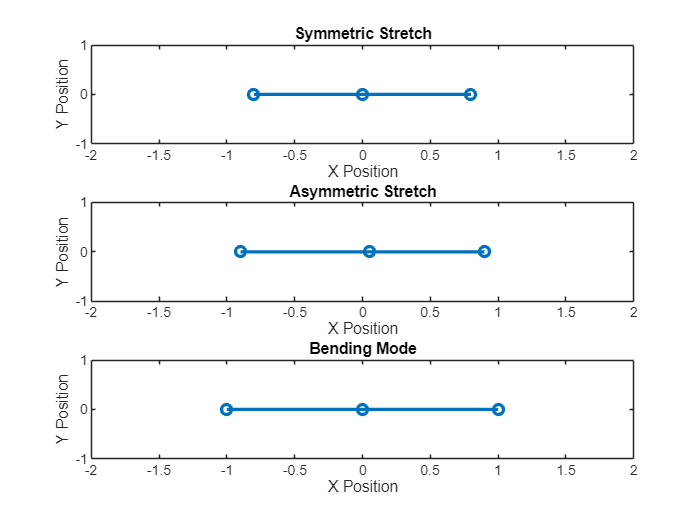

% Define positions of atoms at rest
x_O1 = -1; % Position of oxygen 1
x_C = 0;   % Position of carbon
x_O2 = 1;  % Position of oxygen 2

% Create a figure window
figure;
hold on;
axis equal;
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('X Position');
ylabel('Y Position');
title('Normal Modes of CO2 Molecule');
grid on;

% Number of frames for animation
frames = 100;

% Define time vector for oscillation
t = linspace(0, 2*pi, frames);

% Plot the normal modes
for i = 1:frames
    % Symmetric stretch mode
    symStretch_O1 = x_O1 + 0.2 * cos(t(i));
    symStretch_O2 = x_O2 - 0.2 * cos(t(i));
    symStretch_C = x_C;
    
    % Asymmetric stretch mode
    asymStretch_O1 = x_O1 + 0.1 * cos(t(i));
    asymStretch_C = x_C + 0.05 * cos(t(i));
    asymStretch_O2 = x_O2 - 0.1 * cos(t(i));
    
    % Bending mode (in 2D, moving perpendicular to bond axis)
    bend_O1 = [x_O1, 0.1 * sin(t(i))];
    bend_C = [x_C, -0.05 * sin(t(i))];
    bend_O2 = [x_O2, 0.1 * sin(t(i))];
    
    % Clear the previous plots
    clf;
    
    % Plot Symmetric Stretch (1D)
    subplot(3, 1, 1);
    plot([symStretch_O1, symStretch_C, symStretch_O2], [0, 0, 0], 'o-', 'LineWidth', 2);
    title('Symmetric Stretch');
    xlim([-2, 2]);
    ylim([-1, 1]);
    xlabel('X Position');
    ylabel('Y Position');
    
    % Plot Asymmetric Stretch (1D)
    subplot(3, 1, 2);
    plot([asymStretch_O1, asymStretch_C, asymStretch_O2], [0, 0, 0], 'o-', 'LineWidth', 2);
    title('Asymmetric Stretch');
    xlim([-2, 2]);
    ylim([-1, 1]);
    xlabel('X Position');
    ylabel('Y Position');
    
    % Plot Bending Mode (2D)
    subplot(3, 1, 3);
    plot([bend_O1(1), bend_C(1), bend_O2(1)], [bend_O1(2), bend_C(2), bend_O2(2)], 'o-', 'LineWidth', 2);
    title('Bending Mode');
    xlim([-2, 2]);
    ylim([-1, 1]);
    xlabel('X Position');
    ylabel('Y Position');
    
    pause(0.05); % Pause for animation
end

**(D)** Assume an initial state such that one oxygen atom is displaced away from the carbon by 50% of the nominal distance, the carbon and the other oxygen are in their nominal positions, and there are initially no motions. Plot the displacement of all three atoms over 3-5 periods in the same figure.

The nominal distance is 1.16 angstrom.

use,


$$\begin{array}{l}
\overset{\ldotp \ldotp }{x_1 } =-\omega_1^2 \left(x_1 -x_2 \right)=k x_2 -k x_1 \\
\overset{\ldotp \ldotp }{x_2 } =-\omega_2^2 \left(x_2 -x_1 \right)-\omega_2^2 \left(x_2 -x_3 \right)=k x_1 -k x_2 +k x_3 -kx_2 \\
\overset{\ldotp \ldotp }{x_3 } =-\omega_1^2 \left(x_3 -x_2 \right)=k x_2 -k x_3 ,\\
\mathrm{where}\;\omega_1^2 =\frac{k}{m_O }\;\mathrm{and}\;\omega_2^2 =\frac{k}{m_C }
\end{array}$$


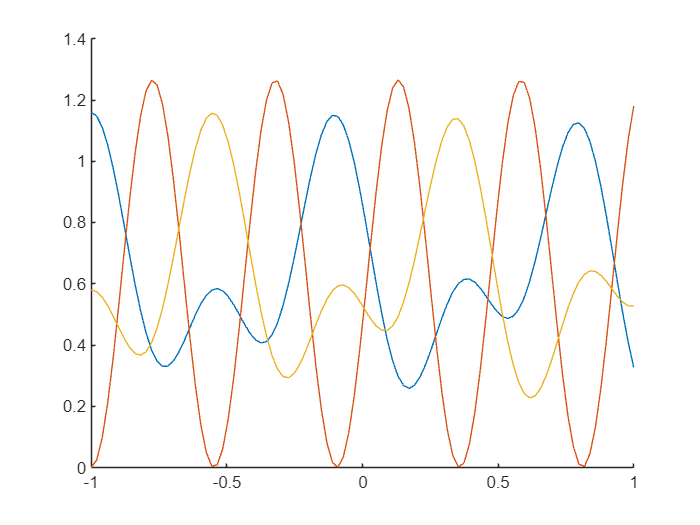

function xdot = odefun(t, x)
    k = 840 ;
    m_C = 12 ; % Mass of carbon in kg
    m_O = 16; % Mass of oxygen in kg
    omega1 = sqrt(k/m_O) ;
    omega2 = sqrt(k/m_C) ;
    % extract varibles
    x1 = x(1) ;
    x1dot = x(2) ;
    x2 = x(3) ;
    x2dot = x(4) ;
    x3 = x(5) ;
    x3dot = x(6) ;

    % set up diff eqs
    xdot(1) = x1dot ;
    xdot(2) = -omega1^2*(x1 - x2) ;
    xdot(3) = x2dot ;
    xdot(4) = -omega2^2*(x2 - x1) - omega2^2*(x2 - x3) ;
    xdot(5) = x3dot ;
    xdot(6) = -omega1^2*(x3 - x2) ;

    % Return column state vector
    xdot = xdot' ;
end
ix = [1.16, 0, 0, 0, 1.16 / 2, 0] ;
tspan = linspace(-1, 1, 100) ;
[t, x] = ode45(@odefun, tspan, ix) ;
clf
hold on
for i = 1:2:6
    plot(t, x(:, i))
end